# z-Domain analysis of LCL grid-connected inverter-10kHz switch frequency and 20kHz sample-control freqency

## Initialization of parameters

Sample and control frequency: 20kHz

Delay of capacitor current: 1.5 steps

clear ;
close all ;
clc;
% Setup bode options
MyBodeOptions = bodeoptions ;
MyBodeOptions.FreqUnits = 'Hz';
MyBodeOptions.Grid = 'on';
MyBodeOptions.Title.String = '';
MyBodeOptions.XLabel.String = '频率';
MyBodeOptions.XLabel.FontSize = 14 ;
MyBodeOptions.XLim = {[10, 2e4/2]};
MyBodeOptions.YLabel.String = {'幅值', '相位'};
MyBodeOptions.YLabel.FontSize = 14 ;
MyBodeOptions.YLim = {[-50, 50], [ -600, 0]} ;
% MyBodeOptions.PhaseWrapping = 'on';

% 10kHz sampling frequency
Ts_Control = 5e-5; 
fs = 1/Ts_Control ;

% s and z 
s = tf([1,0], 1);
z = tf([1,0], 1, Ts_Control) ;

L1 = 3.8e-3 ;
L2 = 2.2e-3 ;
C = 10e-6 ;

disp("The resonant frequency of LCL inverter is:");

The resonant frequency of LCL inverter is:


w_res = sqrt((L1 + L2) / (L1 * L2 * C)) ;
f_res = w_res / (2 * pi) 

f_res = 1.3483e+03


w_r = sqrt(1/(L2 * C ) ) ;

disp("The 1/6 sampling frequency is:");

The 1/6 sampling frequency is:


fs_6 = fs/6

fs_6 = 3.3333e+03

## Pole-Zero Map_the stability gaurantee without RC 

The control diagram is as below: 

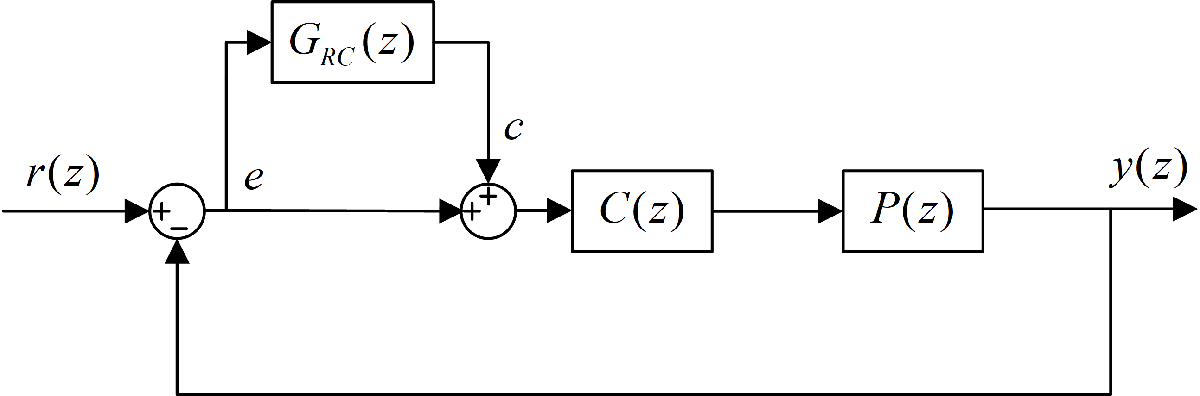


$$T_{o}(z) = \frac{C(z)P(z)}{1 + C(z)P(z)}$$


And from [<Control Techniques for LCL-Type Grid-Connected Inverters>](https://www.springer.com/us/book/9789811042768), considering the digital control delay and PWM transport delay, the transfer function of loop gain is as below:


$$C(z)P(z) = \frac{G_{c}(z)}{\omega_{r}(L_{1} + L_{2})} \frac{\omega_{r} T_{s} (z^2 - 2 z \cos\omega_{r}T_{s} + 1) - (z-1)^2 \sin\omega_{r}T_{s}}{(z-1) \left[ z(z^2 - 2 z \cos\omega_{r}T_{s} + 1) + (z - 1)\frac{K_{d}\sin\omega_{r}T_{s}}{\omega_{r}L_{1}}  \right]}$$


Kd = 25 ; % damping coefficient
Kp = 18 ;
Ki = 18000 ;
Gc_pi = Kp + Ki / s ;
% Gc_z_pi = c2d(Gc_pi, Ts_Control, 'tustin') ;
Gc_z_pi = c2d(Gc_pi, Ts_Control) ;

CP_z = Gc_z_pi * ...
    (w_res * Ts_Control * (z^2 - 2 * z * cos(w_res * Ts_Control) + 1 ) -...
    (z - 1)^2 * sin(w_res * Ts_Control)) / ...
    ( w_res * (L1 + L2) * ...
    (z - 1) * ( z* (z^2 - 2 * z * cos(w_res * Ts_Control) + 1) + ...
    (z - 1) * Kd / (w_res * L1) * sin(w_res * Ts_Control)) );

% CP_z = minreal(CP_z, 1e-4 );
disp('The bode plot of loop gain without repetitive controller') ;

The bode plot of loop gain without repetitive controller


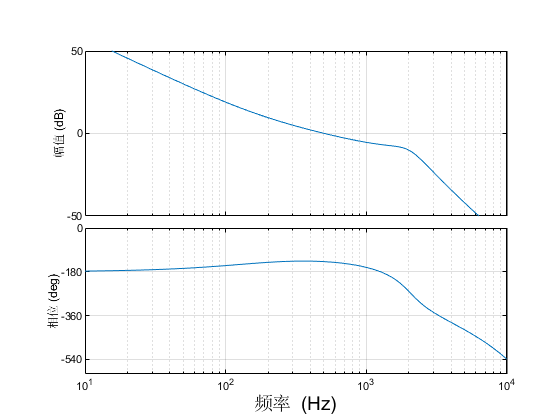

figure 
bode(CP_z, MyBodeOptions)


T_o_z = CP_z / (1 + CP_z) ;
T_o_z = minreal(T_o_z, 1e-4) ;

S_o_z = 1 - T_o_z ;

disp('The bode plot of T(z):')

The bode plot of T(z):


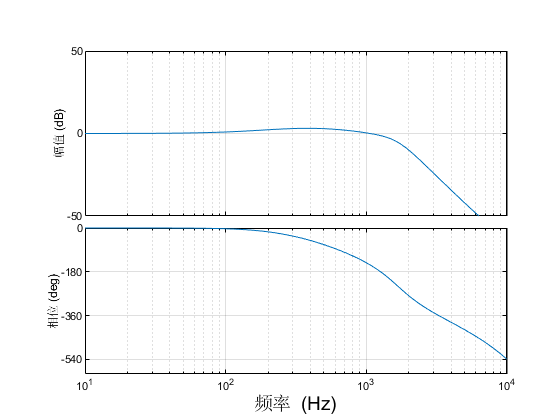

figure 
bode(T_o_z, MyBodeOptions)


% Ensure that the original PI controlled system is stable.
% All the poles of the system should be in the unit circle.
disp('To see if all the poles are in the unit circle:')

To see if all the poles are in the unit circle:


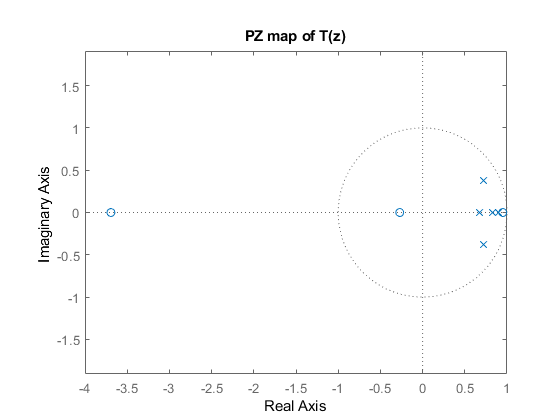

figure 
pzmap(T_o_z)
title 'PZ map of T(z)'
axis equal 

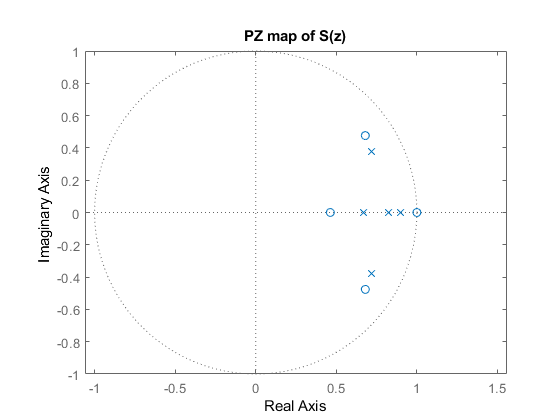


figure 
pzmap(S_o_z)
axis equal
title 'PZ map of S(z)' 


disp('It is reasonable that T(z) and S(z) have the same poles')

It is reasonable that T(z) and S(z) have the same poles


## Stability gaurantee with weighted RC

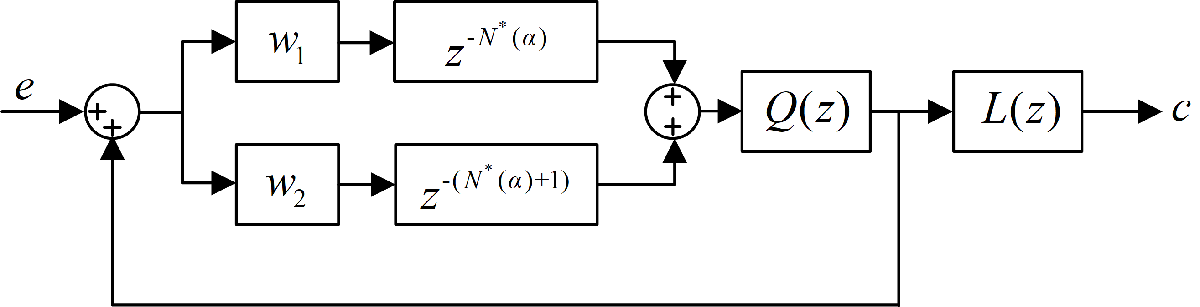

The control structure of weighted RC is as above.  

For CRC with fixed delay, the stability condition is:


$$\left|Q\left(z\right)\left(1-T_o \left(z\right)L\left(z\right)\right)\right|<1$$


For RC with varying delay, the stability condition is :


$$\left|Q\left(z\right)\left(1-T_o \left(z\right)L\left(z\right)\right)\right|<\frac{1}{M_h -M_l +1}$$


Ideally, $L\left(z\right)$ is the inverse of the plant. However, it is not always physically feasible or convenient, and the model of plant may change during different circumstances.

In practice, $L\left(z\right)$ can be constructed as 3 parts:

- phase lead part, lead m steps: $z^m$

- low pass filter

- gain coefficient $k_{\mathrm{rc}}$

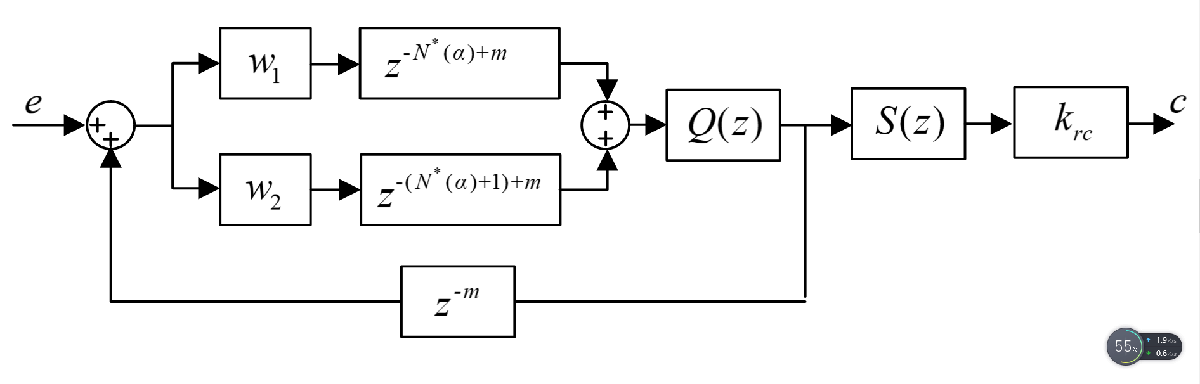

From $\left|Q\left(z\right)\left(1-T_o \left(z\right)L\left(z\right)\right)\right|<1$, we can get:


$$\left|\left(1-T_o \left(z\right)L\left(z\right)\right)\right|<\frac{1}{\left|Q\left(z\right)\right|}$$


Let see the bode diagram of $T_o \left(z\right)$ to see the gain-phase characteristic:

figure Name 'Bode Diagram of T(z)'
bode(T_o_z, MyBodeOptions)


lead_steps = 11 ;

wf = 1000 * 2 * pi;
damp_ratio = 1.414

damp_ratio = 1.4140

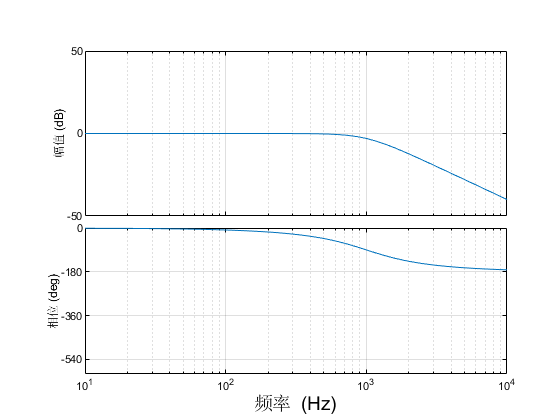

L_s =  wf^2 / ( wf ^2 + damp_ratio * wf * s + s^2) ;
figure
bode(L_s, MyBodeOptions) ;


G_filter_z = c2d(L_s, Ts_Control, 'tustin') ;

k_rc = 1 ;
L_z = k_rc * z^lead_steps * G_filter_z;

c2d(L_s, Ts_Control, 'tustin')


ans =
 
  0.01979 z^2 + 0.03958 z + 0.01979
  ---------------------------------
       z^2 - 1.565 z + 0.6437
 
Sample time: 5e-05 seconds
Discrete-time transfer function.



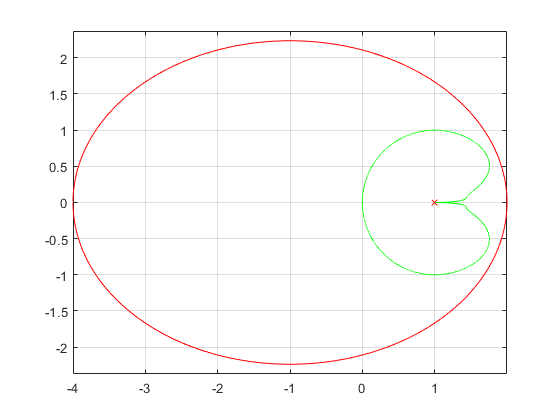


kq = 0.6;

Q_z = (1 - kq) * 0.5 * z + kq + (1 - kq) * 0.5 / z ;

theta = -pi : 0.01 : pi ;
r = 1 ./ ( kq + (1 - kq) * cos(theta) ) ;
bound_stability = 1 + r .* cos(theta) + 1i * r .* sin(theta) ;


R_z = 1 - T_o_z * L_z ;

[h, w ] = freqresp(R_z, 2 * pi * ( 1:1:fs/2) ) ;
h = reshape(h, size(w)) ;
theta_p = w / fs ;

h = abs(h) ;
r_z_to_see = 1 + h .* cos(theta_p) + 1i * h .* sin(theta_p) ;

figure ;
plot(bound_stability, 'r-')
hold on ;
scatter(1,0, 'rx')
axis equal
grid on ;

plot(r_z_to_see, 'g-')
r_z_to_see = 1 + h .* cos(- theta_p) + 1i * h .* sin(- theta_p) ;
plot(r_z_to_see, 'g-')